## **CT - scan project.**

Robin Nillson  --  Halldór Stefán Laxdal.

addpath('.\functions')

load('CTdata.mat')
2*floor(size(g,1)/(2*sqrt(2)))

ans = 100

*"Type load('data.mat') to load a number of sinogram. The first exercise uses sinogram g. The size can be found with size(g) in MATLAB. The output should be 144 180, which shows that the size of the array (sinogram) is 144 rows ´ 180 columns. The sinogram was formed based on multiple parallel beam (*$-71\le l\le 72$* ) projections of an object from 180 different directions: 0 to 179 degrees with a step size of 1 degree."*

### PART A: Back projection

*"A1: Write down the expression for reconstruction using back-projection and explain the meaning of each term in the equation."*

$b_{\theta \;} \left(x,y\right)=g\left(\mathrm{xcos}\theta +\mathrm{ysin}\;\theta \;,\theta \;\right)\;$where $g\left(\cdot ,\cdot \;\right)\;$is the sinogram image and $\theta$ is angle of which the CT-scanner was rotated comared to the body:

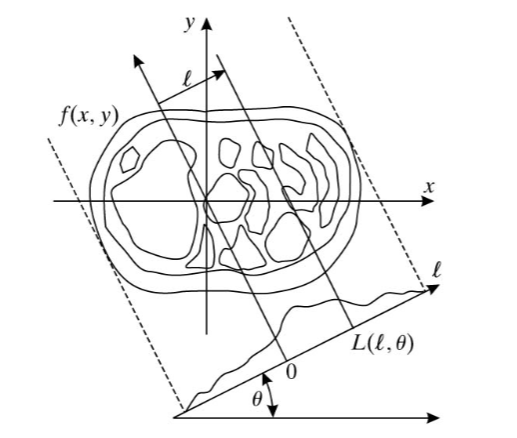

where $L\left(l,\theta \right)$is a line in the plane and $f\left(x,y\right)$ is the body. 

*"A2. Compute and plot the image from the back projection of the sinogram data at *$\theta ={30}^o$*."*

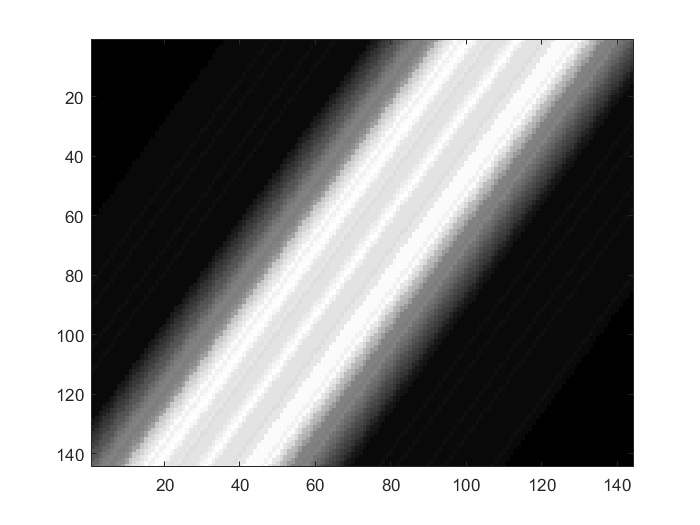

theta = 30;
back_proj = back_projection_theta(g, theta);
imagesc(back_proj); colormap gray

*"A3. Compute and plot the back projection summation image, with N= 6, 12, 30, 60 and 180, where N is the number of back projections. Multiply the resultant image by the factor of *$\frac{\pi \;}{2N}$*where N is the number of projections. Compare and comment on the results based on different values of N."*

N = 6

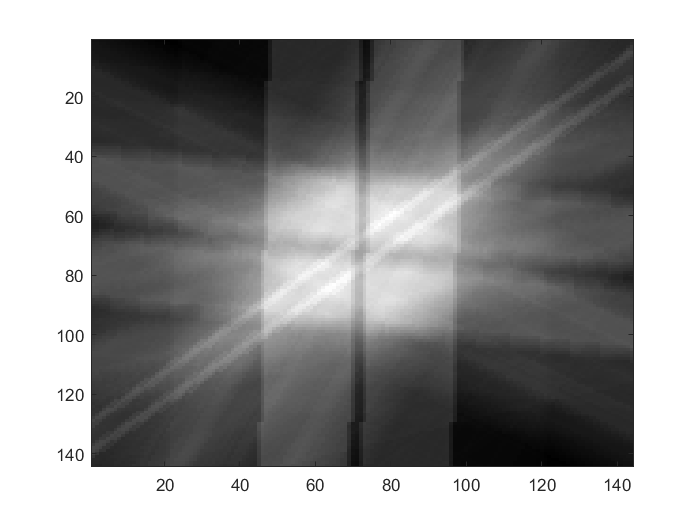

N = 12

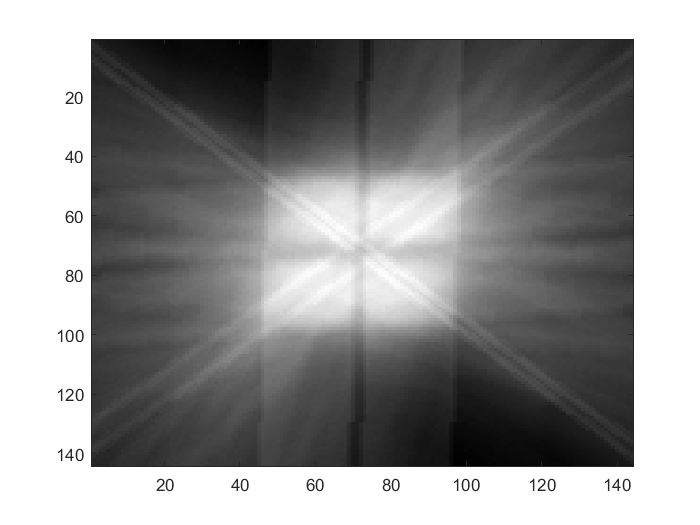

N = 30

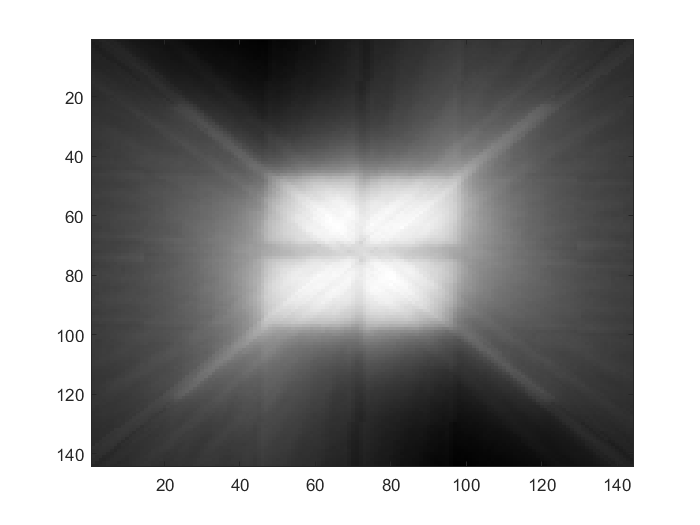

N = 60

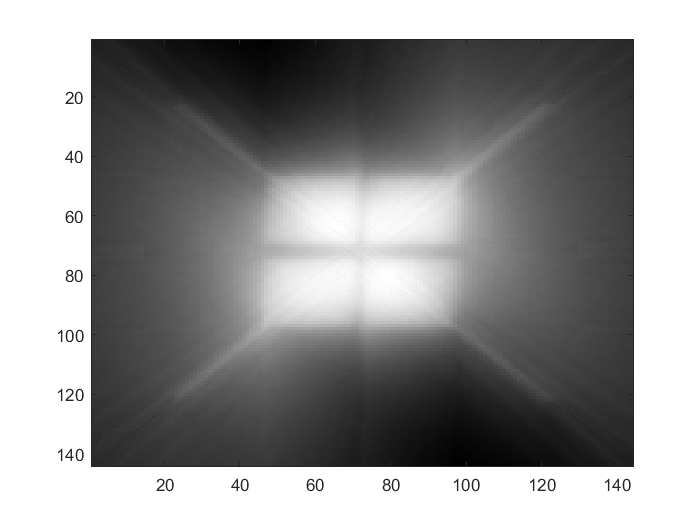

N = 180

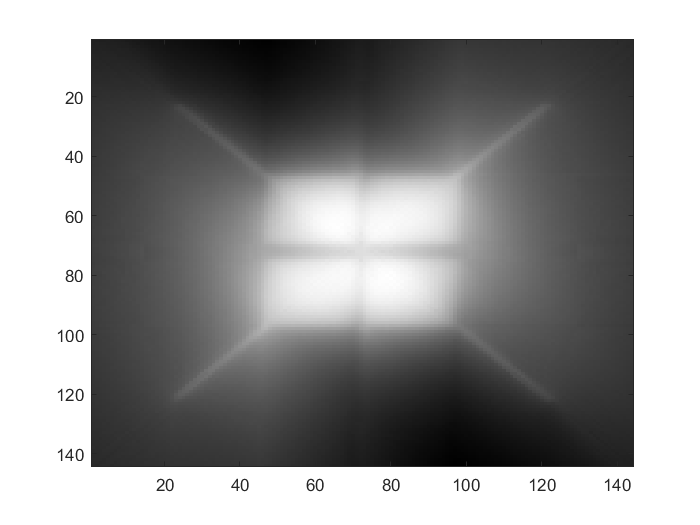

Ns = [6, 12, 30, 60, 180];
for N = Ns
    figure(N)
    N
    back_proj = back_projection(g, N);
    imagesc(back_proj * pi / (2*N)); colormap gray
    % title('num projections: ' + N)
end

### *PART B: * Filtered Back Projection (FBP) 

*"B1. Draw a flow chart to illustrate how to compute the filtered back projection from the sinogram data. List the relevant equations and explain how they are related to each other." *

*"B2. Compute and plot the filtered back projection, with N= 6, 12, 30, 60 and 180, where N is the number of back projections. Multiply the resultant image by the factor of where N is the number of projections. Compare and comment on the results based on different values of N. (Question: Which value of N should we use?) "*

*"B3. Repeat B2 with a Hamming window included in the filtering process. Comment on the results as compared to those in Part B2." *

### PART C. Convolution Back Projection (CBP) 

*"C1. Explain the differences between filtered back projection and convolution back projection."*

*"C2. Implement the convolution back projection algorithm with a Hamming window. Comment on the results as compared to those in Part B3." *

*"C3. Compare and comment on the advantages and disadvantages of using FBP versus CBP."* 

### D. Fan-Beam Projections 

*"D1. What is fan-beam projection and fan-beam reconstruction? How many different geometries are there for fan-beam projection? Describe each of these." *

*"D2. Can we directly apply the implemented algorithm(s) in part B and C to measurements from some of the fan-beam projection geometries described in D1? Explain why. "*

### E. Real CT-images 

*"You also get two additional filed containing sinograms. With load('data.mat') also the sinograms g2 and g3 are loaded. With size(g2) in MATLAB the size of the matrix is found, it should be 1095 180. The third sinogram g3 should have size 895 360. The sinogram g2 was formed based on multiple parallel beam projections of an object from 180 different directions: 0 to 179 degrees with a step size of 1 degree. The sinogram g3 was formed based on multiple parallel beam projections of an object from 360 different directions: 0 to 179.5 degrees with a step size of 0.5 degrees. "*

*"E1. Reconstruct these two images using the three reconstruction methods that you have implemented. You can do this for N = 180, and N = 360, respectively otherwise use the settings for each algorithm that resultet in the best reconstruction. "*

*"E2. Compare these images and comment on similarities or differences in the reconstruction results. What do you need to do to improve the reconstruction even further?"* 